# Descriptive Statistics Live Script 1

Data Science for Engineers II

Author: Dimitar Ninevski

## Prepare workspace

close all;
clear;

## Load a single file from the shiploader data from March

[file, path] = uigetfile;
fullFileName = fullfile(path, file);
load(fullFileName);

## Convert data to matrix

dataMat = dataTT{:,:};

Take the first channel

firstChannel = dataMat(:,1);

Compute some statistical values

meanX = mean(firstChannel);
medianX = median(firstChannel);
modeX = mode(firstChannel);
stdX = std(firstChannel);
iqrX = iqr(firstChannel);
q25 = quantile(firstChannel, 0.25);
q75 = quantile(firstChannel, 0.75);

## Plot the histogram of the data

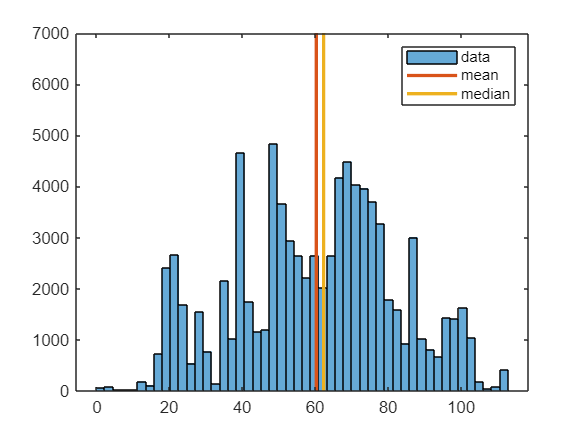

fig1 = figure;
histogram(firstChannel, 50);
hold on
plot([meanX, meanX], [0,7000], 'LineWidth',2);
plot([medianX, medianX], [0,7000], 'LineWidth',2);
legend('data', 'mean', 'median')

## Plot the boxplot of the data

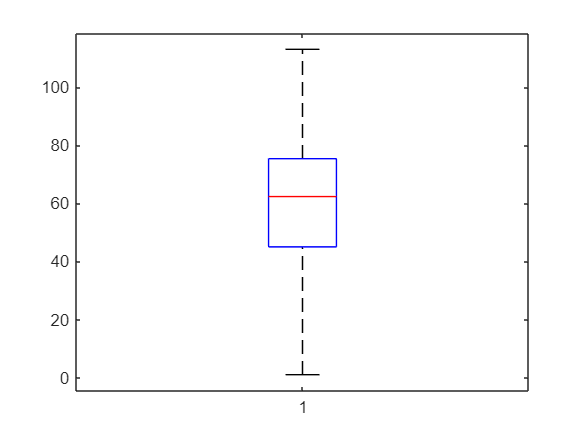

fig2 = figure;
boxplot(firstChannel);

## Create a table for the results

size = [1, 6];
varNames = ["Mean", "Median", "std", "IQR", "Q25", "Q75"];
varTypes = ["double", "double", "double", "double", "double", "double"];
stats = table('Size',size,'VariableTypes',varTypes, ...
    'VariableNames',varNames);
stats.Mean(1) = meanX;
stats{1,2} = medianX;
stats.std(1) = stdX;
stats.IQR(1) = iqrX;
stats.Q25(1) = q25;
stats.Q75(1) = q75;
%table(meanX, medianX, stdX, iqrX, q25, q75)